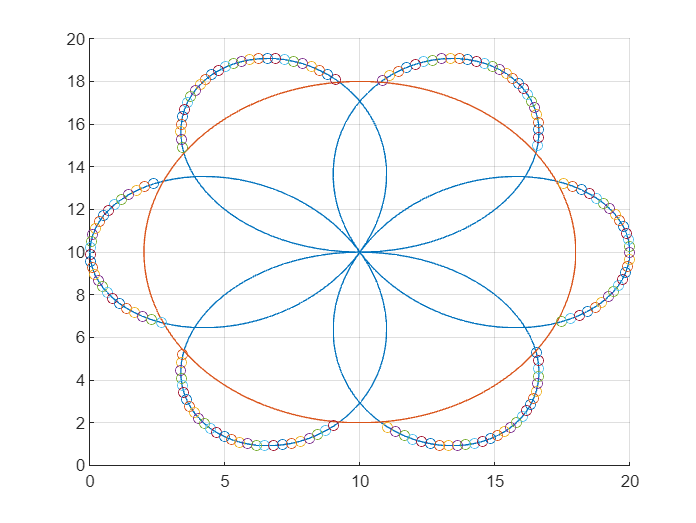

n = 3; % numerador del factor k
d = 2; % denominador del factor k
k = n/d; % Factor que determina la forma de la rosa (Ver Wikipedia)
r = 8; % Radio del círculo que "suaviza"
centro = 10; % Desplazamiento de toda la figura del punto 0,0
a = 10; % Amplitud de la figura

res = 400; % Resolución: Cantidad de puntos de la trayectoria

theta = linspace(pi/2, 4.5*pi,res);
recta = linspace(10, 20, 2);
x = a.*cos(k*theta).*cos(theta)+centro;
y = a.*cos(k*theta).*sin(theta)+centro;

% Función que haga un vector desde 10,10 hasta todos los puntos de la flor.
% Si la norma de este vector es mayor que el radio del círculo, se
% toma para los puntos finales.

d = 0; % Inicializar la distancia.
trayectoriaX = [0 0]; % Inicializar vectores de la trayectoria 
trayectoriaY = [0 0]; % TO DO: Encontrar una manera más elegante  
for i = 1:length(theta) % Hasta el tamaño de theta porque "x" y "y" toman su tamaño de theta.
    % Calcula la distancia entre el centro y cada punto de la flor (pitágoras)
    d = sqrt((x(i)-centro)^2+(y(i)-centro)^2);
    if d > r % Si la distancia calculada es mayor que el radio del círculo entonces...
        trayectoriaX(i) = x(i); % ...conserva la dupla
        trayectoriaY(i) = y(i);
    end
end

trayectoriaX = trayectoriaX(trayectoriaX>0); % Limpia todos los ceros que quedaron...
trayectoriaY = trayectoriaY(trayectoriaY>0); % ...en ambos vectores

hold on
plot(x, y)
plot(r*cos(theta)+centro,r*sin(theta)+centro)

for i = 1:length(trayectoriaY)
    scatter(trayectoriaX(i), trayectoriaY(i))
    pause(0.001)
end
xlim ([0 2*centro])
ylim ([0 2*centro])
grid on

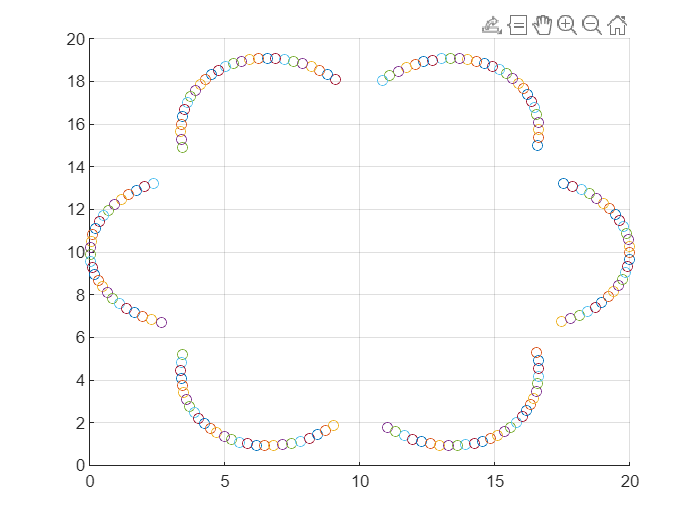


% Un arreglo para separar cada pétalo en cada componente X y Y
petal_1x = zeros(1,length(trayectoriaY));
petal_2x = zeros(1,length(trayectoriaY));
petal_3x = zeros(1,length(trayectoriaY));
petal_4x = zeros(1,length(trayectoriaY));
petal_5x = zeros(1,length(trayectoriaY));
petal_6x = zeros(1,length(trayectoriaY));
petal_1y = zeros(1,length(trayectoriaY));
petal_2y = zeros(1,length(trayectoriaY));
petal_3y = zeros(1,length(trayectoriaY));
petal_4y = zeros(1,length(trayectoriaY));
petal_5y = zeros(1,length(trayectoriaY));
petal_6y = zeros(1,length(trayectoriaY));

% Luego evlúa cada punto X y Y en la trayectoria para ver en qué zona se
% encuentra, y dependiendo de esto se asigna a un pétalo.
for i=1:length(trayectoriaX)
    if trayectoriaX(i) < 10 && trayectoriaY(i) < 6 
        petal_1x(i) = trayectoriaX(i);
        petal_1y(i) = trayectoriaY(i);
    end
    if trayectoriaX(i) < 10 && trayectoriaY(i) > 6 && trayectoriaY(i) < 14
        petal_2x(i) = trayectoriaX(i);
        petal_2y(i) = trayectoriaY(i);
    end
    if trayectoriaX(i) < 10 && trayectoriaY(i) > 14 
        petal_3x(i) = trayectoriaX(i);
        petal_3y(i) = trayectoriaY(i);
    end
    if trayectoriaX(i) > 10 && trayectoriaY(i) > 14 
        petal_4x(i) = trayectoriaX(i);
        petal_4y(i) = trayectoriaY(i);
    end
    if trayectoriaX(i) > 10 && trayectoriaY(i) > 6 && trayectoriaY(i) < 14
        petal_5x(i) = trayectoriaX(i);
        petal_5y(i) = trayectoriaY(i);
    end
    if trayectoriaX(i) > 10 && trayectoriaY(i) < 6 
        petal_6x(i) = trayectoriaX(i);
        petal_6y(i) = trayectoriaY(i);
    end
end

% Se organiza la trayectoria
trayectoria_finalX = [petal_4x petal_3x petal_2x petal_1x petal_6x petal_5x];
trayectoria_finalY = [petal_4y petal_3y petal_2y petal_1y petal_6y petal_5y];

trayectoria_finalX = trayectoria_finalX(trayectoria_finalX>0); % Limpia todos los ceros que quedaron...
trayectoria_finalY = trayectoria_finalY(trayectoria_finalY>0); % ...en ambos vectores

figure;
for i = 1:length(trayectoria_finalY)
    hold on
    xlim ([0 2*centro])
    ylim ([0 2*centro])
    grid on
    scatter(trayectoria_finalX(i), trayectoria_finalY(i))
    pause(0.001)
end